# Team 3: Hexapod Robot Trajectory Single Leg Pose Demonstrator

#### Gary Encinas, Justin Fossum, Jason Munger, and Mithulesh Ramkumar

## Building The Model

This code was derived and adjusted from our group script called "Hexapod_Robot_Joint_Space_Motion_Model.mlx" in which we built leg six of the hexapod robot in the rigid body model.

### Environment Setup

First, we should remove items from workspace, freeing up system memory, and clear current command window.

close all; % Close all current figure windows
clear; % Remove items from workspace, freeing up system memory
clc; % Clear current command window

### Load the Needed Variables

Since this information was iniitially generated by Jason, this section of code will read in the saved workedspace variable. In a full implementation, all of these scripts would just be functions called by an overarching script/program that passes the needed variables from one script to the next.

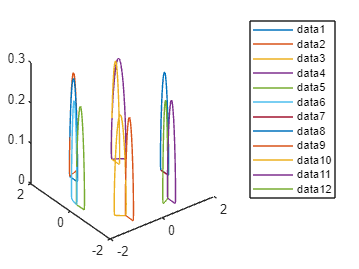

load(".\From Jason\Straight Walk\leg_traj_full.mat")
load(".\From Jason\Straight Walk\Joint_Angles.mat")
straight_traj = leg_traj_full/1000;
straight_traj(3,:,:) = straight_traj(3,:,:) + 0.08;
straight_joint_angles = reshape(Joint_Angles(:,2,:),3,66);

load(".\From Jason\Rotate in Place\leg_traj_full.mat")
load(".\From Jason\Rotate in Place\Joint_Angles.mat")
rotate_traj = leg_traj_full/1000;
rotate_traj(3,:,:) = rotate_traj(3,:,:) + 0.08;
rotate_joint_angles = reshape(Joint_Angles(:,2,:),3,66);

for i=1:size(leg_traj_full,3)
    traj = straight_traj(:,:,i);
    traj(3,:,:) = traj(3,:,:) - 0.08;
    plotted_straight_traj = plot3(traj(1,:),traj(2,:),traj(3,:));
    hold on
    traj = rotate_traj(:,:,i);
    traj(3,:,:) = traj(3,:,:) - 0.08;
    plotted_rotate_traj = plot3(traj(1,:),traj(2,:),traj(3,:));
end
legend

### Set Controllable Outputs

make_video = true; % Set to output videos or not (true or false)

### Building the Rigid Tree Model

When building this model, the leg length visual meshes are reused, so rather than the full string path every time, we have listed them all as variables in the beginning. Keeping true with that fashion, the DH parameters are only changed by a ratio of $\frac{\pi }{3}$ each new leg so there is a count variable that can be called to index the leg creations.

body_mesh = "..\Robot CAD\STL\Body_Link.STL";
link1_vmesh = "..\Robot CAD\STL\Link_One_L2Out.STL";
link2_vmesh = "..\Robot CAD\STL\Link_Two_640_L3Out.STL";
link3_vmesh = "..\Robot CAD\STL\Link_Three_960_EEOut_MovedFoot_700.STL";

count = 1; % Counting variable for itterating through the legs with the order being 2, 1, 3, 5, 6, 4 for leg names.

a = [0.625 0 0.640 0.960]; % Link lengths as a 1:1.5 leg ratio.
alpha = [0 pi/2 0 -pi/2];
d = [0 0 0 0];
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];

%Building The Robot by creating a rigid body tree
leg_two_model = robotics.RigidBodyTree; %Sets rigid body tree to be called robot for callback use

% Define the bodies and their joints
leg_2 = robotics.RigidBody('leg_2'); %Create Leg 6 Origin of the robot.
leg2_jnt1 = robotics.Joint('leg2_jnt1','fixed'); %Create a fixed joint.
leg2_link1 = robotics.RigidBody('leg2_link1'); %Create Link 1 of the leg 6.
leg2_jnt2 = robotics.Joint('leg2_jnt2','revolute'); %Create a revolute joint.
leg2_link2 = robotics.RigidBody('leg2_link2'); %Create Link 2 of the leg 6.
leg2_jnt3 = robotics.Joint('leg2_jnt3','revolute'); %Create a revolute joint.
leg2_link3 = robotics.RigidBody('leg2_link3'); %Create Link 3 of the leg 6.
leg2_jnt4 = robotics.Joint('leg2_jnt4','revolute'); %Create a revolute joint.

% Specify the body-to-body transformation using DH parameters
setFixedTransform(leg2_jnt1,DHparams(1,:),'dh');
setFixedTransform(leg2_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg2_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg2_jnt4,DHparams(4,:),'dh');

% Specify the body joints
leg_2.Joint = leg2_jnt1;
leg2_link1.Joint = leg2_jnt2;
leg2_link2.Joint = leg2_jnt3;
leg2_link3.Joint = leg2_jnt4;

% Add the STL visual to the body
addVisual(leg_2, "Mesh", body_mesh);

% Add the STL visual to the first link
addVisual(leg2_link1, "Mesh", link1_vmesh);

% Add the STL visual to the second link
addVisual(leg2_link2, "Mesh", link2_vmesh);

% Add the STL visual to the third link
addVisual(leg2_link3, "Mesh", link3_vmesh);

% Attach the sixth Leg
addBody(leg_two_model,leg_2,'base')
addBody(leg_two_model,leg2_link1,'leg_2');
addBody(leg_two_model,leg2_link2,'leg2_link1');
addBody(leg_two_model,leg2_link3,'leg2_link2');

% config = homeConfiguration(leg_two_model);
% figure('Name','Initial Robot State')
% show(leg_two_model,config,"Frames","off");

leg_two_model_moved = rigidBodyTree;
rb = rigidBody('newBaseForFull_Robot');
rb.Joint.setFixedTransform(make_eular_transform(0,0,0.780,0,0,0));
leg_two_model_moved.addBody(rb, 'base');
leg_two_model_moved.addSubtree('newBaseForFull_Robot', leg_two_model);
leg_two_model_moved.DataFormat = 'row';

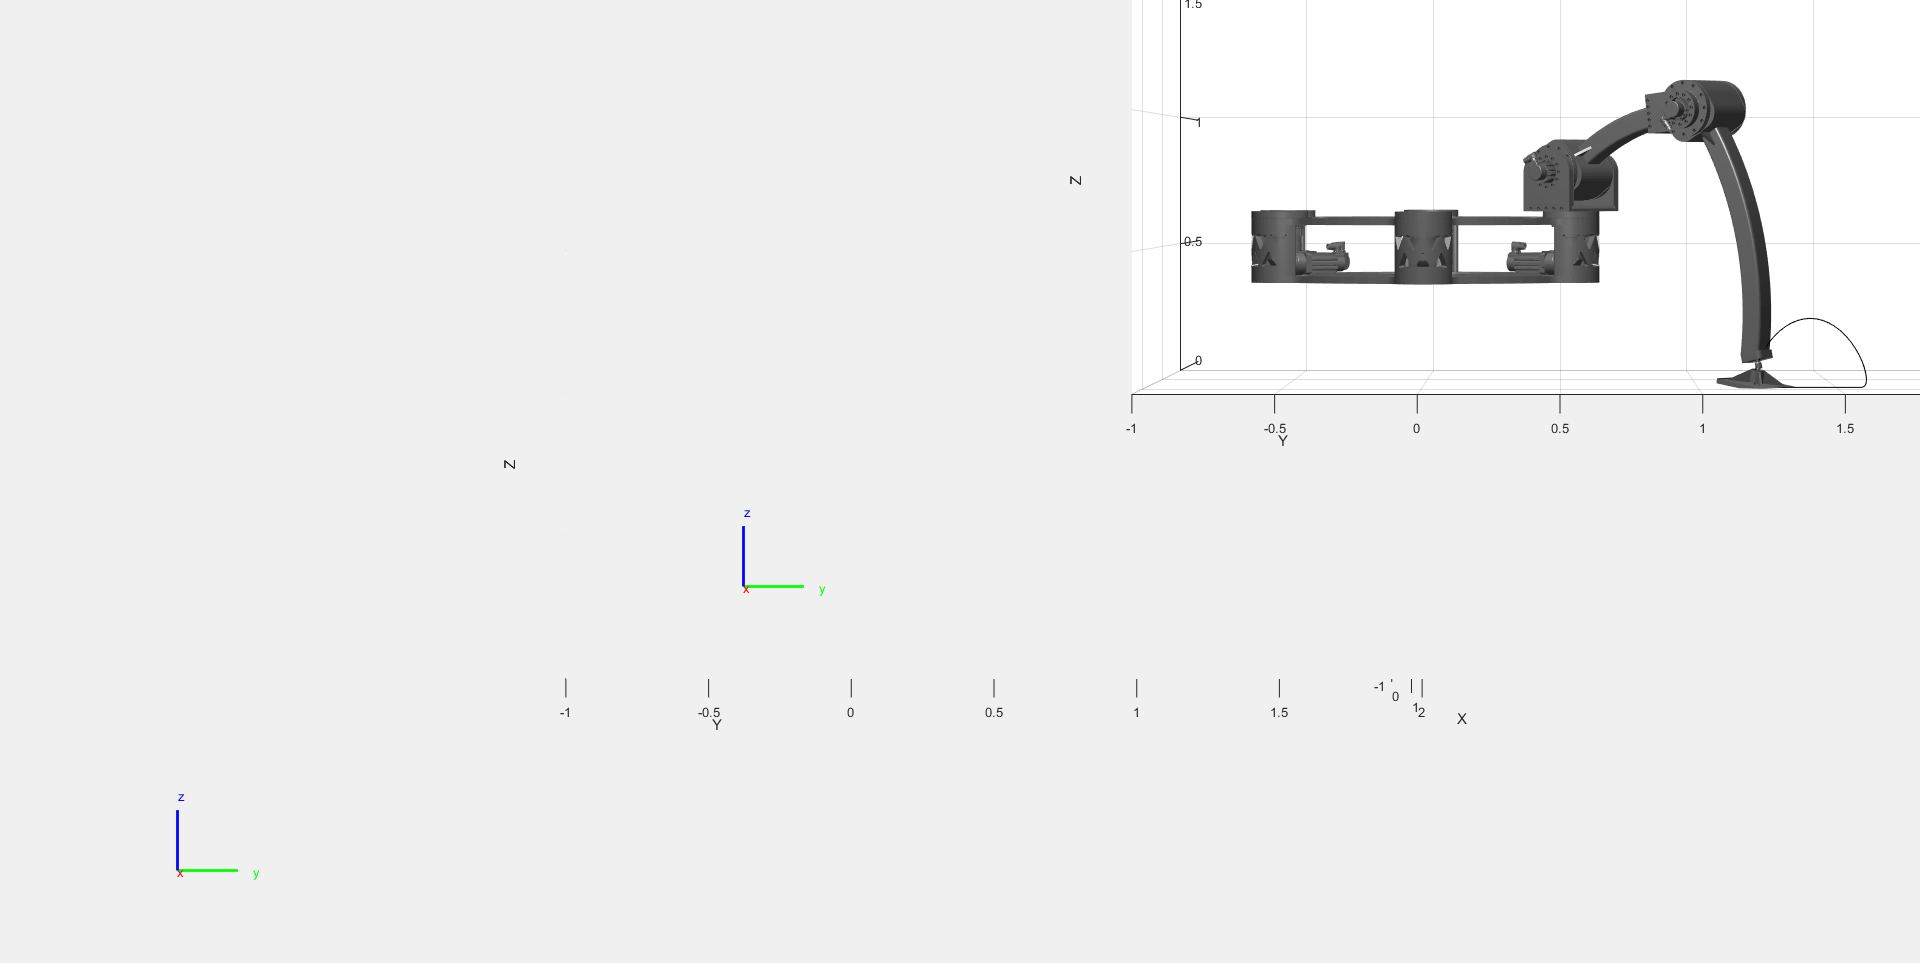

% Plot staight trajectory
figure('Name','Single Leg Staight Trajectories Demonstration',"WindowState","maximized")
for i=1:size(straight_joint_angles,2)
    show(leg_two_model_moved,straight_joint_angles(:,i)',"Frames","off","PreservePlot",false,"FastUpdate",true);
    xlim([-1 1.5])
    ylim([-1 2])
    zlim([0, 1.5])
    
    hold on
    view(135,8)
    traj = straight_traj(:,:,2);
    traj(3,:,:) = traj(3,:,:) - 0.08;
    plotted_straight_traj = plot3(traj(1,:),traj(2,:),traj(3,:),'k');
    drawnow;
    
    if make_video
        G(i) = getframe(gcf); % Creates frame of each incremental movement from top view
    end

    view(2); % Top view of the robot
    drawnow;
    if make_video
        H(i) = getframe(gcf); % Creates frame of each incremental movement from top view
    end
    
    view(180,0); % Front view of robot
    drawnow;
    if make_video
        I(i) = getframe(gcf); % Creates frame of each incremental movement from front view
    end
    
    view(90,0); % Side view of the robot
    drawnow;
    if make_video
        J(i) = getframe(gcf); % Creates frame of each incremental movement from side view
    end
end

if make_video
    % Create video of animation
    movie(G);
    movie(H);
    movie(I);
    movie(J);
    % create the video writer
    writerObj_G = VideoWriter('Single Leg Staight Trajectories Demonstration - 40fsp','MPEG-4');
    writerObj_H = VideoWriter('Single Leg Staight Trajectories Demonstration Top View - 40fsp','MPEG-4');
    writerObj_I = VideoWriter('Single Leg Staight Trajectories Demonstration Front View - 40fsp','MPEG-4');
    writerObj_J = VideoWriter('Single Leg Staight Trajectories Demonstration Side View - 40fsp','MPEG-4');
    writerObj_G.FrameRate = 40;
    writerObj_H.FrameRate = 40;
    writerObj_I.FrameRate = 40;
    writerObj_J.FrameRate = 40;
    % set the seconds per image
    % open the video writer
    open(writerObj_G);
    open(writerObj_H);
    open(writerObj_I);
    open(writerObj_J);
    % write the frames to the video
    for i=1:length(G)
        % convert the image to a frame
        frame_G = G(i);
        frame_H = H(i);
        frame_I = I(i);
        frame_J = J(i);
        writeVideo(writerObj_G, frame_G);
        writeVideo(writerObj_H, frame_H);
        writeVideo(writerObj_I, frame_I);
        writeVideo(writerObj_J, frame_J);
    end
    % close the writer object
    close(writerObj_G);
    close(writerObj_H);
    close(writerObj_I);
    close(writerObj_J);
end

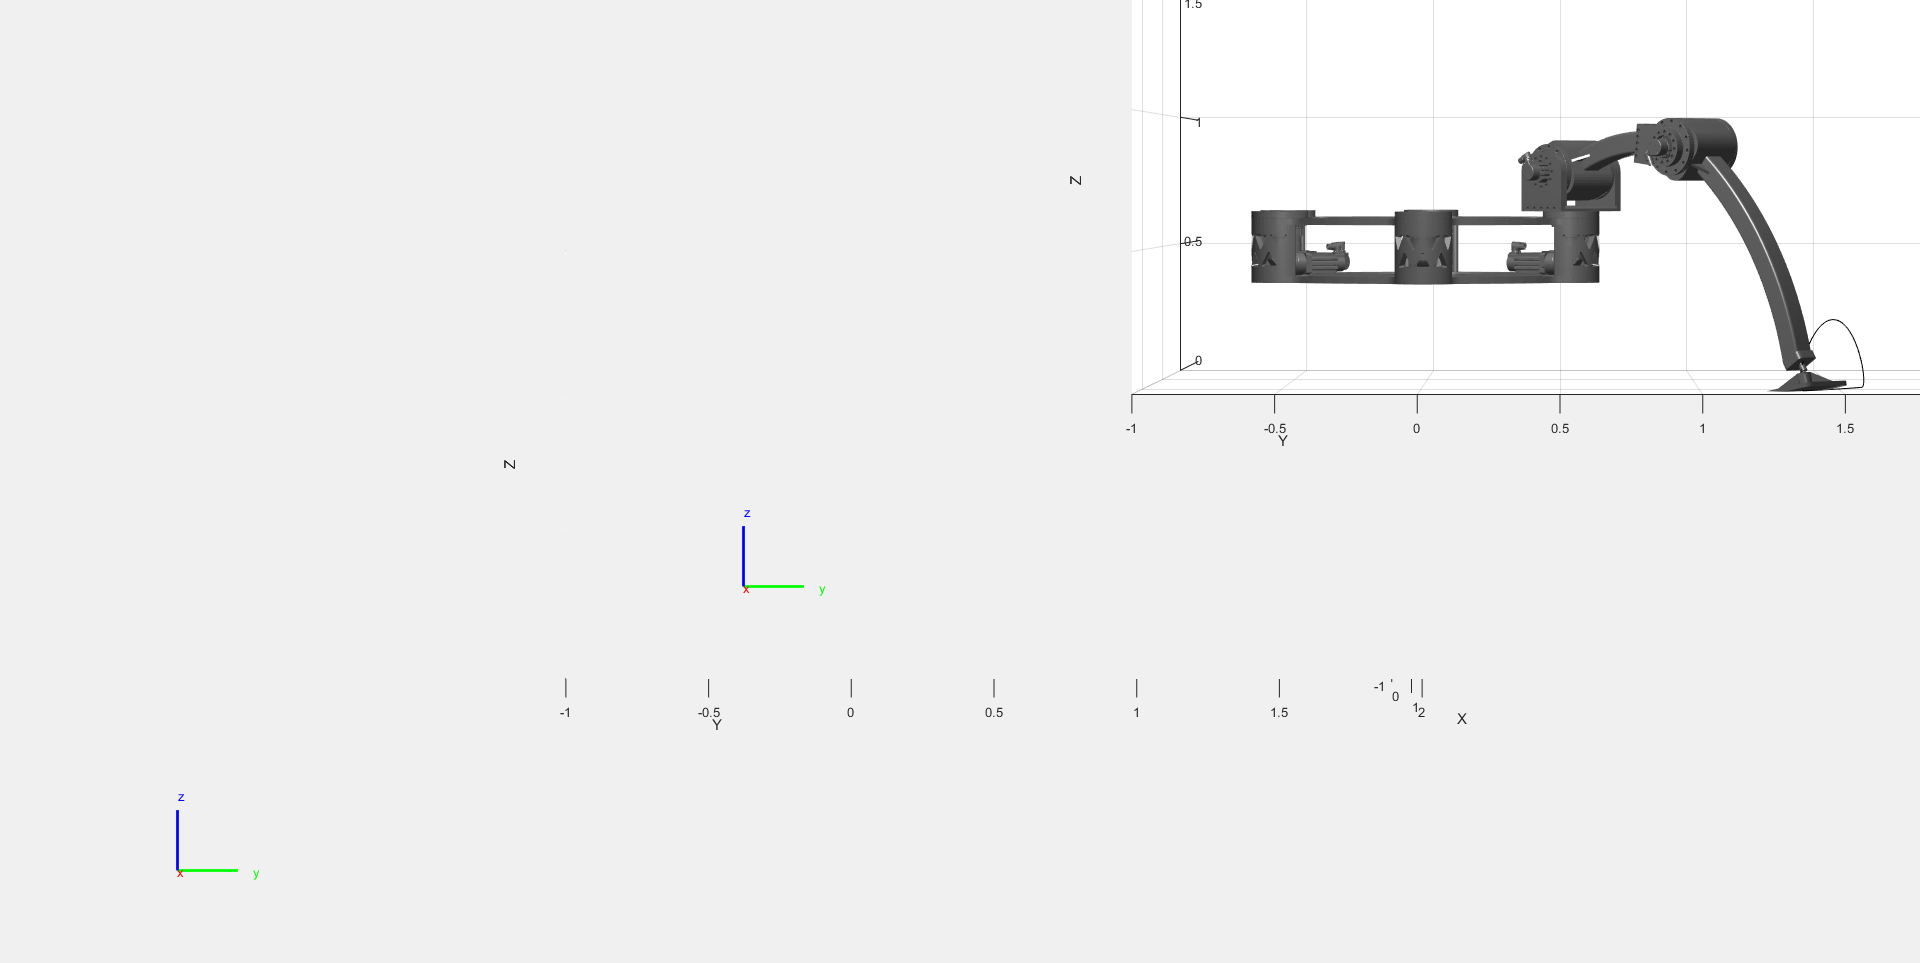



% Plot rotate trajectory
figure('Name','Single Leg Rotate Trajectories Demonstration',"WindowState","maximized")
for i=1:size(rotate_joint_angles,2)
    show(leg_two_model_moved,rotate_joint_angles(:,i)',"Frames","off","PreservePlot",false,"FastUpdate",true);
    xlim([-1 1.5])
    ylim([-1 2])
    zlim([0, 1.5])
    
    hold on
    view(135,8)
    traj = rotate_traj(:,:,2);
    traj(3,:,:) = traj(3,:,:) - 0.08;
    plotted_rotate_traj = plot3(traj(1,:),traj(2,:),traj(3,:),'k');
    drawnow;

    if make_video
        G(i) = getframe(gcf); % Creates frame of each incremental movement from top view
    end

    view(2); % Top view of the robot
    drawnow;
    if make_video
        H(i) = getframe(gcf); % Creates frame of each incremental movement from top view
    end
    
    view(180,0); % Front view of robot
    drawnow;
    if make_video
        I(i) = getframe(gcf); % Creates frame of each incremental movement from front view
    end
    
    view(90,0); % Side view of the robot
    drawnow;
    if make_video
        J(i) = getframe(gcf); % Creates frame of each incremental movement from side view
    end
end

if make_video
    % Create video of animation
    movie(G);
    movie(H);
    movie(I);
    movie(J);
    % create the video writer
    writerObj_G = VideoWriter('Single Leg Rotate Trajectories Demonstration - 40fsp','MPEG-4');
    writerObj_H = VideoWriter('Single Leg Rotate Trajectories Demonstration Top View - 40fsp','MPEG-4');
    writerObj_I = VideoWriter('Single Leg Rotate Trajectories Demonstration Front View - 40fsp','MPEG-4');
    writerObj_J = VideoWriter('Single Leg Rotate Trajectories Demonstration Side View - 40fsp','MPEG-4');
    writerObj_G.FrameRate = 40;
    writerObj_H.FrameRate = 40;
    writerObj_I.FrameRate = 40;
    writerObj_J.FrameRate = 40;
    % set the seconds per image
    % open the video writer
    open(writerObj_G);
    open(writerObj_H);
    open(writerObj_I);
    open(writerObj_J);
    % write the frames to the video
    for i=1:length(G)
        % convert the image to a frame
        frame_G = G(i);
        frame_H = H(i);
        frame_I = I(i);
        frame_J = J(i);
        writeVideo(writerObj_G, frame_G);
        writeVideo(writerObj_H, frame_H);
        writeVideo(writerObj_I, frame_I);
        writeVideo(writerObj_J, frame_J);
    end
    % close the writer object
    close(writerObj_G);
    close(writerObj_H);
    close(writerObj_I);
    close(writerObj_J);
end

function hg_transform = make_eular_transform(x,y,z,a,b,c)
% MAKE_EULAR_TRANSFORM Builds a homogeneous transformation matrix based on
% desired position and rotation. Rotation is in Eular angle.
    arguments
        x (1,1) double {mustBeNumeric, mustBeFinite}
        y (1,1) double {mustBeNumeric, mustBeFinite}
        z (1,1) double {mustBeNumeric, mustBeFinite}
        a (1,1) double {mustBeNumeric, mustBeFinite}
        b (1,1) double {mustBeNumeric, mustBeFinite}
        c (1,1) double {mustBeNumeric, mustBeFinite}
    end

    trans_x = [1, 0, 0, x;
             0, 1, 0, 0;
             0, 0, 1, 0;
             0, 0, 0, 1]; % Translation about the X axis
    trans_y = [1, 0, 0, 0;
             0, 1, 0, y;
             0, 0, 1, 0;
             0, 0, 0, 1]; % Translation about the Y axis
    trans_z = [1, 0, 0, 0;
             0, 1, 0, 0;
             0, 0, 1, z;
             0, 0, 0, 1]; % Translation about the Z axis
    rot_x = [1, 0, 0, 0;
             0, cos(a), -sin(a), 0;
             0, sin(a), cos(a), 0;
             0, 0, 0, 1]; % Rotation about the X axis
    rot_y = [cos(b), 0, sin(b), 0;
             0, 1, 0, 0;
             -sin(b), 0, cos(b), 0;
             0, 0, 0, 1]; % Rotation about the Y axis
    rot_z = [cos(c), -sin(c), 0, 0;
             sin(c), cos(c), 0, 0;
             0, 0, 1, 0;
             0, 0, 0, 1]; % Rotation about the Z axis
    hg_transform = rot_x*rot_y*rot_z*trans_x*trans_y*trans_z; % Built homogeneous transformation matrix
end